# Robotics I - 

#  - 2019

## Exercise 1

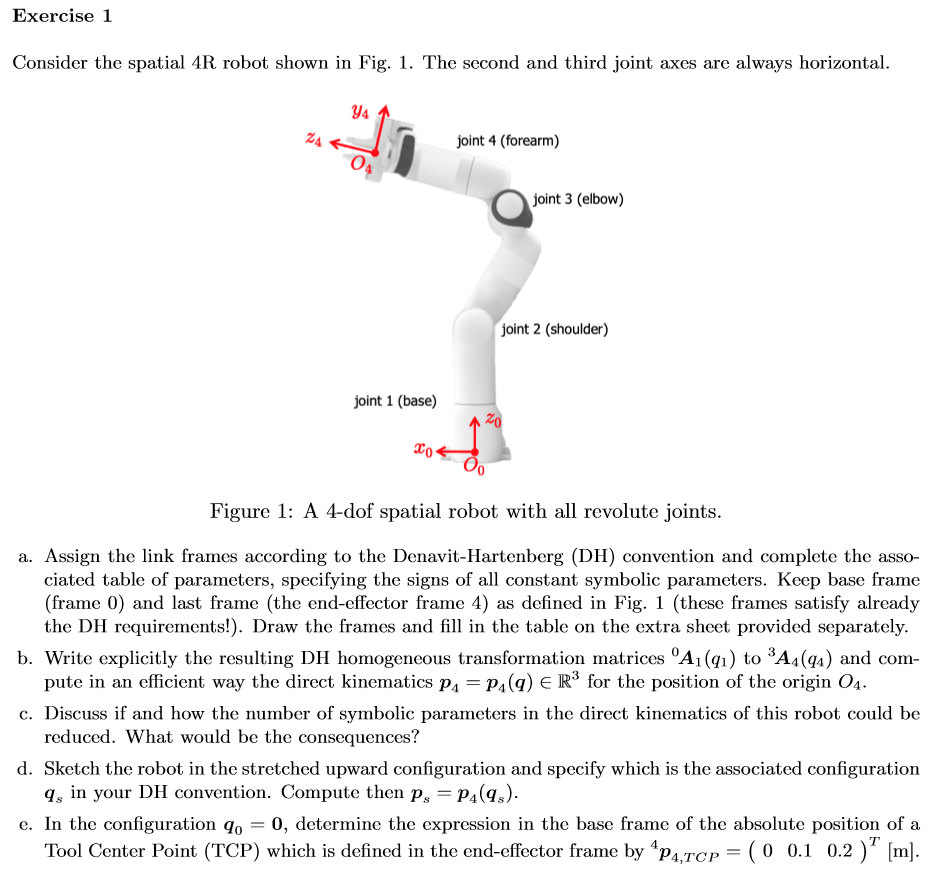

%  %close all
% % % Lengths just to test
% d1_=10;
% d4_=10;
% a2_=10;
% a3_=2;
% % % De Luca's approach
% %  links = [
% %     Revolute('a', 0, 'alpha', -pi/2 ,'d', d1_);
% %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% %     Revolute('a', a3_, 'alpha', -pi/2 ,'d', 0);
% %     Revolute('a', 0, 'alpha', 0 ,'d', d4_);
% %      ];
% % % 
% %  c600 = SerialLink(links);
% %  c600.teach([0 -pi/2 0 -pi/2],'view','y');
% % c600.plot([0  pi/2 20 0],'view','x')
% clear
% sigma = [0,0,0,0]
% n = length(sigma)
% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% dhTable = [-pi/2    , 0     , d(1)  , q(1);
%             0       , a(2)  , 0     , q(2);
%             -pi/2   , a(3)  , 0     , q(3) ; 
%             0       , 0     , d(4)  , q(4)]
% 
%  [T_Total T_Partial,R_Total,R_Partial,P_Total, P_Partial] = getTransformationMatrix(dhTable, 'alpha')
% T_Partial{1}
% p = T_Total(1:3,4); % Position of end effector;
% sincos_ = getShortNotation_SinCos(n);
% pfg_ = toShortNotation(p,sincos_)
% %efficiente way to compute  P
% % %Efficient Computation 4p(p)
% phomvector=[0,0,0,1]';
% n_p=[];
% for inm=[n:-1:1]
%     phomvector=simplify(T_Partial{inm}*phomvector);%optimal way to compute the P vector, uncoment this
%     n_p=phomvector;
% end
% 
% P = phomvector(1:3)
% p4tcp=[0,0.1,0.2,1]';
% q_=[0,0,0,0]';
% n_p=[];
% for inm=[n:-1:1]
%     p4tcp=simplify(T_Partial{inm}*p4tcp);%optimal way to compute the P vector, uncoment this
%     n_p=p4tcp;
% end
% 
% n_p_=subs(n_p,q,q_)

## Exercise 2

% [Jl Ja Jls Jas] = getJacobian(dhTable, sigma, 'alpha')
% 
% % sincos_ = getShortNotation_SinCos(n);
% % Jl_ = toShortNotation(Jl,sincos_)
% % Ja_ = toShortNotation(Ja,sincos_)

% % T_total_ = toShortNotation(T_Total, sincos_)
% % simplify(solve(det(Jl(:,1:n-1))<3))
%  Jl_1=simplify(R_Partial{1}'*Jl);
%  Jl_1_ = toShortNotation(Jl_1,sincos_);

## computing singularities

% [JacobianSinFac,JacobianSinFac_s] = JacobianSingularities(Jl(:,1:n-1),n)
% [JacobianSinFac1,JacobianSinFac1_s] = JacobianSingularities(Jl_1(:,1:n-1),n)

## Finding velocities

% pe = sym('p', [n,1],'real');% I don't kwnow if is only p
% vb=[1 0 1]'
% q_=[0,0,0,0]';
% Jl0_=simplify((subs(Jl,q,q_)))
% rank(Jl0_)
% qda=pe.*null(Jl0_)
% qbd_=([inv(Jl0_(:,1:n-1));zeros(n-1,1)']*vb)
% qp=qda+qbd_

## finding velocity again

% simplify(Jl0_*qp)
% 

## my aproach

% 
%   J = [Jl;Ja];
%   [V,W] = generalkinematics(J,P_Total,1,q);
% %   q_=[0,0,0,0]' %already declared, check it out
%   V_=simplify(subs(V,q,q_))
%   Vb_=[1 0 1]'
%   qbd_=solve(V_==Vb_);
%   [qdvvalues_,qdvnames_,Total_qdvvalues_]=solvetoarray(qbd_,qd)

## exercise 3

clear all;
clc
close all
% Lengths just to test
L1_=0.5;
L2_=0.5;
L_=[L1_,L2_]';
C0_=[0.2,0.3]';
R_=0.15

R_ = 0.1500

v_=3;
% % De Luca's approach
%  links = [
%     Revolute('a', L1_, 'alpha',0,'d', 0);
%     Revolute('a', L2_, 'alpha',0,'d', 0);
% %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% 
%      ];
% % 
%  c600 = SerialLink(links);
%  c600.teach([0 0],'view','top');
% qplot=0:0.01:pi/2;
% for qplot=0:0.1:pi/2
%  c600.plot([0  qplot],'view','top')
% end
sigma = [0,0];
n = length(sigma);
q = sym('q', [n,1],'real');
qd = sym('qd', [n,1],'real');
L = sym('L', [n,1],'real');

qd= sym('qd', [n,1],'real');
Pd = sym('Pd','real');
Pd_d = sym('Pd_d','real');
P_d = sym('P_d','real');
v=sym('v','real');

s = sym('s','real');
Jl = sym('Jl','real');
sx = sym('sx','real');
sy = sym('sy','real');
t = sym('t','real');
Re = sym('Re','real');
R = sym('R','real');
kx = sym('kx','real');
ky = sym('ky','real');
ke=[kx,0;0,ky]

$$ke = \left(\begin{array}{cc} \mathrm{kx} & 0\\ 0 & \mathrm{ky} \end{array}\right)$$

syms s(t);
assumeAlso(s(t),'real')
% syms v(t);
% assumeAlso(v(t),'real')
 syms p(t);
 assumeAlso(p(t),'real')
  syms Re(t);
 assumeAlso(Re(t),'real')
  syms pd(t);
 assumeAlso(pd(t),'real')
  syms e(t);
 assumeAlso(e(t),'real')
   syms ereal(t);
 assumeAlso(ereal(t),'real')
   syms track_err(t);
 assumeAlso(track_err(t),'real')
 
%  Ke = sym('Ke','real');
  syms Skew_(theta1);
 assumeAlso(Skew_(theta1),'real')
% syms f(q_t);
% syms q_t(t);



 theta1=s/R;
 w1=diff(theta1)

$$w1(t) = \frac{\frac{\partial }{\partial t}s\left(t\right)}{R}$$

 pd=C0_+R*([cos(theta1);sin(theta1)]);
 pd_d1=diff(pd)

$$pd\_d1(t) = \left(\begin{array}{c} -\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)\\ \cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right) \end{array}\right)$$

 pd_d2=diff(pd_d1)

$$pd\_d2(t) = \left(\begin{array}{c} -\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)-\frac{\cos\left(\frac{s\left(t\right)}{R}\right)\,{\left(\frac{\partial }{\partial t}s\left(t\right)\right)}^{2}}{R}\\ \cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)-\frac{\sin\left(\frac{s\left(t\right)}{R}\right)\,{\left(\frac{\partial }{\partial t}s\left(t\right)\right)}^{2}}{R} \end{array}\right)$$

% jpd=jacobian(pd)

dhTable = [ 0   ,   L(1)   , 0 , q(1);
            0   ,   L(2)   , 0 , q(2)];

 [T_Total T_Partial,R_Total,R_Partial,P_Total, P_Partial] = getTransformationMatrix(dhTable, 'alpha',false);
 [JL1 Jo1] = getJacobian(dhTable,'RR','alpha');
 %% case ehn  eerror_o=P0-f(q0) different  of zero
 %Rotated tracking error
%  e=pd-f(q_t(t))
p=P_Total(1:end-1,:)

$$p = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\\ L_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

Rf=[-sin(theta1),cos(theta1);-cos(theta1) ,-sin(theta1)] % de dónde carajos sale

$$Rf(t) = \left(\begin{array}{cc} -\sin\left(\frac{s\left(t\right)}{R}\right) & \cos\left(\frac{s\left(t\right)}{R}\right)\\ -\cos\left(\frac{s\left(t\right)}{R}\right) & -\sin\left(\frac{s\left(t\right)}{R}\right) \end{array}\right)$$

%  skew(s)
%  track_err=R_f*e



## Luca aproach

%p=e-pd;

e=pd-p

$$e(t) = \left(\begin{array}{c} R\,\cos\left(\frac{s\left(t\right)}{R}\right)-L_{2}\,\cos\left(q_{1}+q_{2}\right)-L_{1}\,\cos\left(q_{1}\right)+\frac{1}{5}\\ R\,\sin\left(\frac{s\left(t\right)}{R}\right)-L_{2}\,\sin\left(q_{1}+q_{2}\right)-L_{1}\,\sin\left(q_{1}\right)+\frac{3}{10} \end{array}\right)$$

% e=inv(Re)*track_err
Rf_d1=diff(Rf)

$$Rf\_d1(t) = \left(\begin{array}{cc} -\frac{\cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} & -\frac{\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R}\\ \frac{\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} & -\frac{\cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} \end{array}\right)$$


Rf_d11=Rf*skew(-w1)

$$Rf\_d11(t) = \left(\begin{array}{cc} -\frac{\cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} & -\frac{\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R}\\ \frac{\sin\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} & -\frac{\cos\left(\frac{s\left(t\right)}{R}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{R} \end{array}\right)$$

e_d1=-(Rf'*ke*Rf+skew(-w1))*e;
%v=e_d1-pd_d1;%diff(p,t)

% Vsym=shortdiff(v,{e,pd}',t,true,1)

temp_dev = 2×1 cell array
    {1×1 symfun}
    {1×1 symfun}


Error using sym>convertChar (line 1479)
Character vectors and strings in the first argument can only specify a variable or number. To evaluate character vectors and strings representing symbolic expressions, use 'str2sym'.

Error in sym>tomupad (line 1245)
        S = convertChar(x);

Error in 


% Re_d1=Re*Skew_(theta1);
% track_err=Re*ereal

Jl=JL1(1:end-1,:);

## asnwering a

% v=sym('v',[2,1],'real')
%  q_d1=simplify(subs(inv(Jl)*v))
% % when the end-effector is already in the position to do a perfect circle
% % is not needed a control the equation is:
% 
% s_=0; % in this case
% % v=Jl*qd
%  l_var1=[L(1),L(2),R]';
%  l_var2={R,s}';
% 
%  l_var1_=[L1_,L2_,R_]';
%  l_var2_={R_,s_}';
% 
%  pd_=vpa(subs(pd,l_var2,l_var2_))
% 
%  p_=vpa(subs(p,l_var1,l_var1_))
% q0=solve(pd_==p_)
% [qdvvalues_,qdvnames_,Total_qdvvalues_]=solvetoarray(q0,qd)
% % shortdiff(yd2,{s,v}',t,true,2)
%  l_var1=[L(1),L(2),R]';
% 
%  l_var1_=[L1_,L2_,R_]';
% q_d1_=subs(q_d1,l_var1,l_var1_);
% q_d1_=subs(q_d1_,v,[0,3]');
% 
% digits(4)
% % qdvvalues1_(:,1)=-v_*[0;1]
% q_d1_=vpa(subs(q_d1_,q,qdvvalues_(:,:))) %%I've believe that I'm right
% % q_dtdown=[7.141,-4.4]'%[7.605,-12.2]'
% % vt_2=Jl*q_dtdown
% % vt_2=subs(vt_2,l_var1,l_var1_);
% % vt2_=vpa(subs(vt_2,q,qdvvalues_(:,1)))
% % 
% % q_dtup=[7.605,-12.2]'
% % vt_1=Jl*q_dtup
% % vt_1=subs(vt_1,l_var1,l_var1_);
% % vt1_=vpa(subs(vt_1,q,qdvvalues_(:,2)))


## b when is in any side that shit

qoff_=[0,pi/6]'
v=e_d1-pd_d1;
 q_d1=simplify(subs(inv(Jl)*v));
 s_=0;
 ll1={s,R}';
 ll1_={s_,R_}'
 ke_=[1/0.1,0;0,1/0.05];
 Rf_=subs(Rf,ll1,ll1_ )
 Reff_=Rf_'*ke_*Rf_
 skew_0=skew(v_/R_)
%  q_d1_=simplify(subs(q_d1,ke,ke_));
 pd_=simplify(subs(pd,ll1,ll1_))
p_=simplify(subs(p,[q;L],[qoff_;L_]))
q_d1_l=[20.2224,-22.4186]' 
term1=skew_0+Reff_
pd_d1=v_*[0,-1]' 
pd_d1=sym('pd_d1',[2,1],'real')
e_=pd_-p_
e_=vpa(subs(e_,[q;L],[qoff_;L_]))
q_d1_=inv(Jl)*(pd_d1+term1)*e_
q_d1_2=vpa(subs(q_d1_,[q;L],[qoff_;L_]))
pbd_d1=solve(q_d1_l==q_d1_2)
[pdvarray_,pdvnames_,pd_d1_] = solvetoarray(pbd_d1,pd_d1)